# Tema 2.2 - Derivación Numérica

## Ejemplo 1 

Calcular la derivada en todos los puntos por forward difference y por backward difference.

x=[0:0.2:0.4];y=[0 0.7414 1.3718];
disp([x',y'])

         0         0
    0.2000    0.7414
    0.4000    1.3718



yp0 = (y(2) - y(1))/(x(2) - x(1))   % derivada en x = 0 (forward)
yp2 = (y(3) - y(2))/(x(3) - x(2))   % derivada en x = 0.2 (forward)
yp4 = (y(3) - y(2))/(x(3) - x(2))

## Ejemplo 2

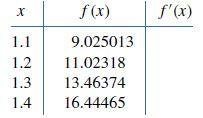

Calcular la derivada en todos los puntos con una fórmula de orden el más alto posible orden, O(h) i O(h^2)

x=linspace(1.1,1.4,4); y=[9.025013,11.02318,13.46374,16.44465];
disp([x',y'])

ERRORES. Los datos se corresponden a la función $y=e^{2x}$ la derivada es $y'=2e^{2x}$. Crear tabla para visualitzar error absoluto en las fórmulas usadas

## Ejemplo 3

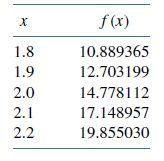

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

x=linspace(1.8,2.2,5); y=x.*exp(x); disp([x',y'])

#### Ejercicio 1 - CNGuia-Lab9

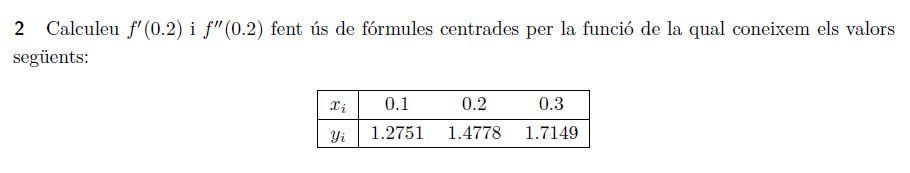

#### Ejercicio 2 - CNGuia-Lab9

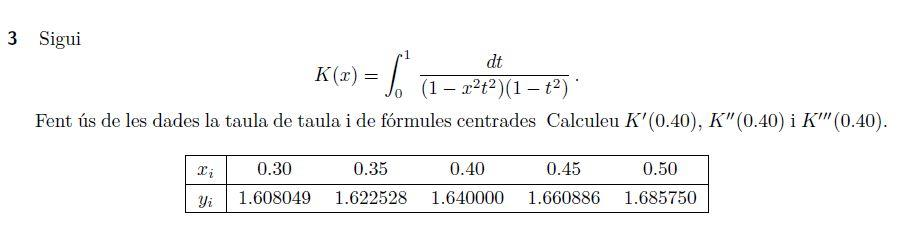

# Error en las fórmulas de diferenciación numérica 

#### PRÀCTICA 22 - CNGuia-Lab9

% Calcul de la derivada de ln(x) en x = 2
 f = @(x) log(x);
 
 k = 0:14;
 h = 1./10.^k;  % Los valores de h van tendiendo a 0.
 
 fp = zeros(1,15);
 for n = 1:15
     % fp(n) = (f(2+h(n)) - f(2)) / h(n); % formula forward
     fp(n) = (f(2+h(n)) - f(2-h(n))) / (2*h(n)); % formula centrada
 end
 
 er = abs(fp - 0.5);    % 0.5 es el valor de la derivada de ln(x) en x = 2.
 
 format long g
 results = array2table([k; h; fp; er]', "VariableNames", {'k', 'h', 'fp(k)', 'er'})

results = 15×4 table
    k       h             fp(k)                   er         
    __    ______    _________________    ____________________

     0         1    0.549306144334055      0.0493061443340548
     1       0.1    0.500417292784913    0.000417292784913204
     2      0.01    0.500004166729162    4.16672916214722e-06
     3     0.001    0.500000041666615    4.16666150471201e-08
     4    0.0001    0.500000000416834    4.16833678684725e-10
     5     1e-05    0.500000000008827    8.82671713497984e-12
     6     1e-06    0.500000000014378    1.43778322581056e-11
     7     1e-07    0.499999999736822    2.63177923898184e-10
     8     1e-08    0.499999996961265    3.03873548546107e-09
     9     1e-09    0.500000041370185    4.13701854995452e-08
    10     1e-10    0.500000041370185    4.13701854995452e-08
    11     1e-11    0.50000004137018

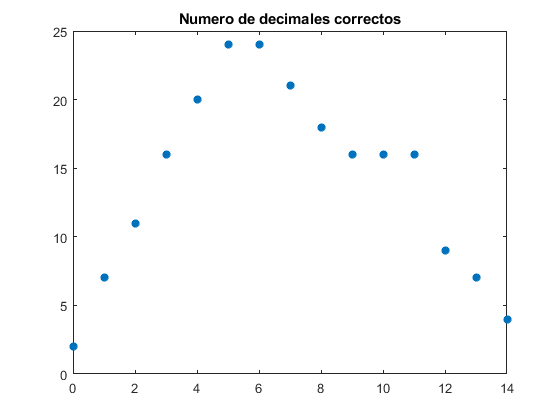

 plot(k,fix(-log(2*er)), '*', 'LineWidth', 2);
 title("Numero de decimales correctos");

# Approximate Derivatives with diff

Consultar la ayuda de Matlab para la instrucción diff y trasladar ejemplo función seno. 

# Derivación simbólica con Matlab 

Ejemplos extraídos del help

#### **Differentiate Function**

Find the derivative of the function `sin(x^2)`.

syms f(x)


Find the value of the derivative at `x = 2`. Convert the value to double.

**Differentiation with Respect to Particular Variable**

Find the first derivative of this expression: $sin(xt^2)$

syms x t


**Mixed Derivatives**

Differentiate this expression with respect to the variables `x` and `y`:

syms x y
diff(x*sin(x*y), x, y)

#### Document preparat per Mª Àngela Grau Gotés (prof. responsable MN)